Here we are simulating control of the robot shown above. We have already obtained the dynamics of this robot in the dynamics section. The robot starts at joint position $\theta =0$. Here $L=1$, $m_1 =m_2 =m_3 =1$, and $I_3 =0\ldotp 1$. 

 We will modify the code as needed so that the robot reaches for $\theta_d$ using multivariable PD control with gravity compensation:


$$\tau =K*P\left(\theta_d -\theta \right)-K*D*\dot{\theta} +g\left(\theta \right)$$


**CASE 3: A simulation where again, **$K_p =I$** and **$K_d =I$**. But this time, the desired position will be:**


$$\theta_d =\left\lbrack \begin{array}{c}
2*\cos \left(0\ldotp 5*\pi *t\right)\\
2*\sin \left(0\ldotp 5*\pi *t\right)\\
\frac{\pi }{2}
\end{array}\right\rbrack$$



$${\dot{\dot{\theta} } }_d =$$

$$\left\lbrack \begin{array}{c}
-\pi *\sin \left(0\ldotp 5*\pi *t\right)\\
\pi *\cos \left(0\ldotp 5*\pi *t\right)\\
0
\end{array}\right\rbrack$$


Here we are reaching for the $\theta_d$ specified above, and keeping the best performing gains as we found in case 2, $K_p$ and $K_d$.

$K_p$ = $I*25$, $K_d$ = $I*25$

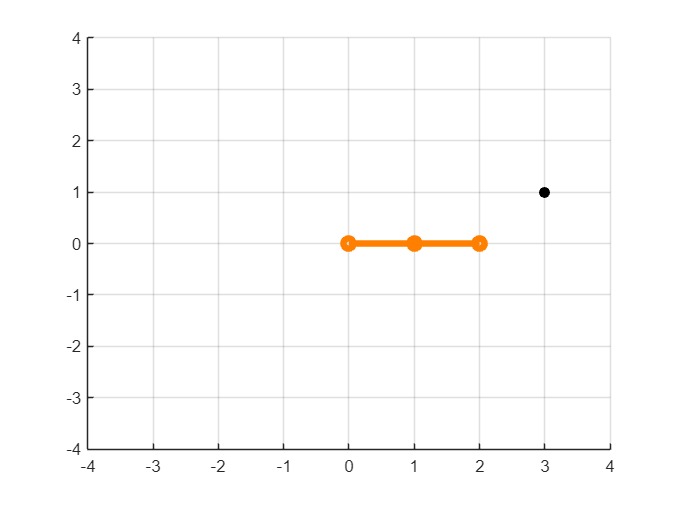

close all
clear
clc

% create figure
figure
axis([-4, 4, -4, 4])
grid on
hold on

% save as a video file
v = VideoWriter('Case_3.mp4', 'MPEG-4');
v.FrameRate = 100;
open(v);

% pick your system parameters
m1 = 1;
m2 = 1;
m3 = 1;
I3 = 0.1;
L = 1;
g = 9.81;
deltaT = 0.01;

% initial conditions
theta = [0; 0; 0];
thetadot = [0; 0; 0];
thetadotdot = [0; 0; 0];
time = 0;

% forward kinematics to end-effector
S1 = [0;0;0;1;0;0];
S2 = [0;0;0;0;1;0];
S3 = [0;0;1;0;-L;0];
S = [S1, S2, S3];
M3 = [eye(3), [2*L;0;0]; 0 0 0 1];

% For Case 3
Kp = eye(3)*25;
Kd = eye(3)*25;

M0 = [eye(3), [L;0;0]; 0 0 0 1];
M1 = [eye(3), [L;0;0]; 0 0 0 1];
M2 = [eye(3), [L;0;0]; 0 0 0 1];

for idx = 1:1000

    % get desired position
    theta_d = [2*cos(pi*time/2); 2*sin(pi*time/2); pi/2];
    thetadot_d = [-pi*sin(pi*time/2); pi*cos(pi*time/2); 0];
    T_d = fk(M3, [S1 S2 S3], theta_d);
    
    % plot the robot
    p0 = [0; 0];
    T1 = fk(M1, S1,theta(1:1,:));
    p1 = T1(1:2,4);                         % position of end of link 1
    T2 = fk(M2,[S1 S2],theta(1:2,:));
    p2 = T2(1:2,4);                         % position of end of link 2
    T3 = fk(M3,[S1 S2 S3],theta(1:3,:));
    p3 = T3(1:2,4);                         % position of end of link 3
    P = [p0, p1, p2, p3];
    cla;
    plot(P(1,:), P(2,:), 'o-', 'color',[1, 0.5, 0],'linewidth',4)
    
    % plot the desired position
    plot(T_d(1,4), T_d(2,4), 'ok', 'MarkerFaceColor','k')
    drawnow
    frame = getframe(gcf);
    writeVideo(v,frame);
    
    % Mass matrix
    M = [m1 + m2 + m3, 0, -L*m3*sin(theta(3));
            0, m2 + m3, L*m3*cos(theta(3));
            -L*m3*sin(theta(3)), L*m3*cos(theta(3)), m3*L^2 + I3];

    % Coriolis matrix
    C = [0, 0, -L*thetadot(3)*m3*cos(theta(3));
        0, 0, -L*thetadot(3)*m3*sin(theta(3));
        0, 0,                 0];

    % Gravity vector
    G = [0; g*m2 + g*m3; L*g*m3*cos(theta(3))];
    
    % Reference from a journal and a book Modern Robotics (Just for reference and knowledge)
    e1 =    theta_d - theta;
    e1dot = thetadot_d - thetadot;

    % Choose your controller tau
    tau = Kp*(theta_d-theta) + Kd*(thetadot_d - thetadot) + G;
    
    % integrate to update velocity and position
    thetadotdot = M \ (tau - C*thetadot - G);
    thetadot = thetadot + deltaT * thetadotdot;
    theta = theta + deltaT * thetadot;
    time = time + deltaT;

end


close(v);
close all